# Applying the Lawler-Fujita algorithm and distortion subtraction by Gao et al. (2017) to real STM images

Just like Real_2.mlx but with the ability to handle hexagonal lattice images.

## 1    Importing an image

[~, lattice] = loadsxm('FGT_nq_2204240001.sxm', 1);

% lattice = double(im2gray(imread('lawler.png')));

name = "Kirsty 1";

#### Image specifications

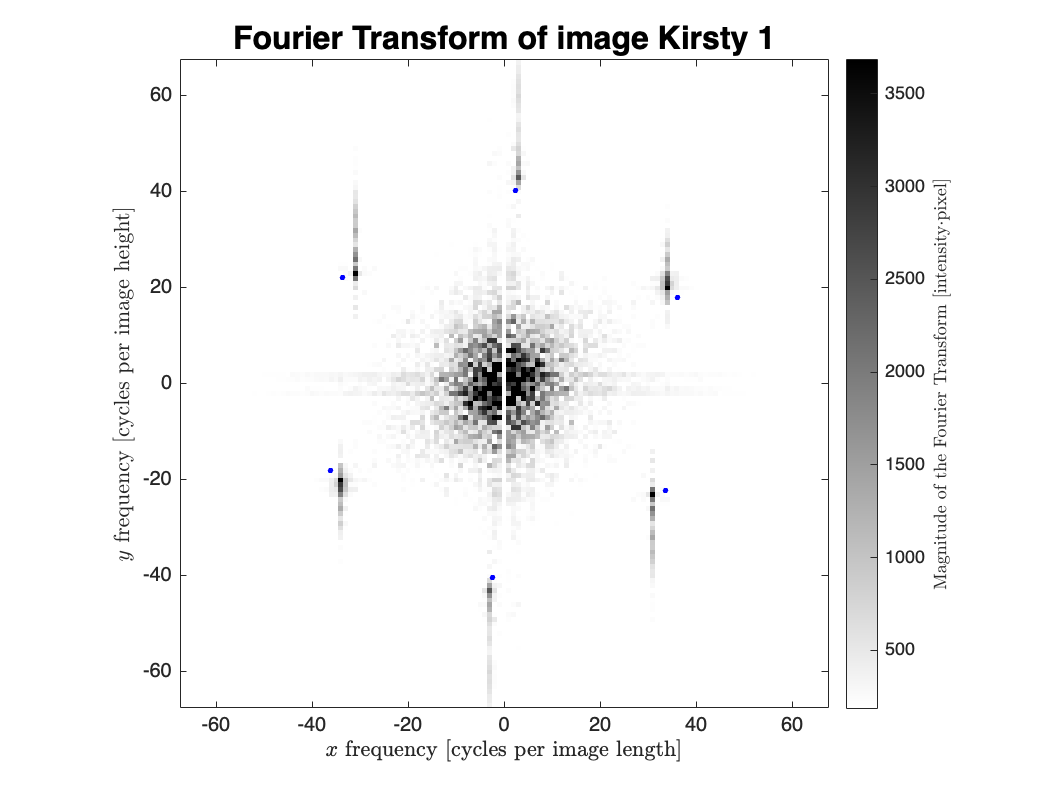

myFFT() estimates that the 2D lattice is perfect hexagonal.


[image_height, image_length] = size(lattice);
lattice = reshape(normalize(lattice(:)),image_height,image_length);

lattice = (lattice-mean(lattice,2))./std(lattice,1,2);
% normalize per row. Adapted from Kirsty's topo042401.m

[lattice_fft, Qbragg] = myFFT(lattice,name,cscale='linear');

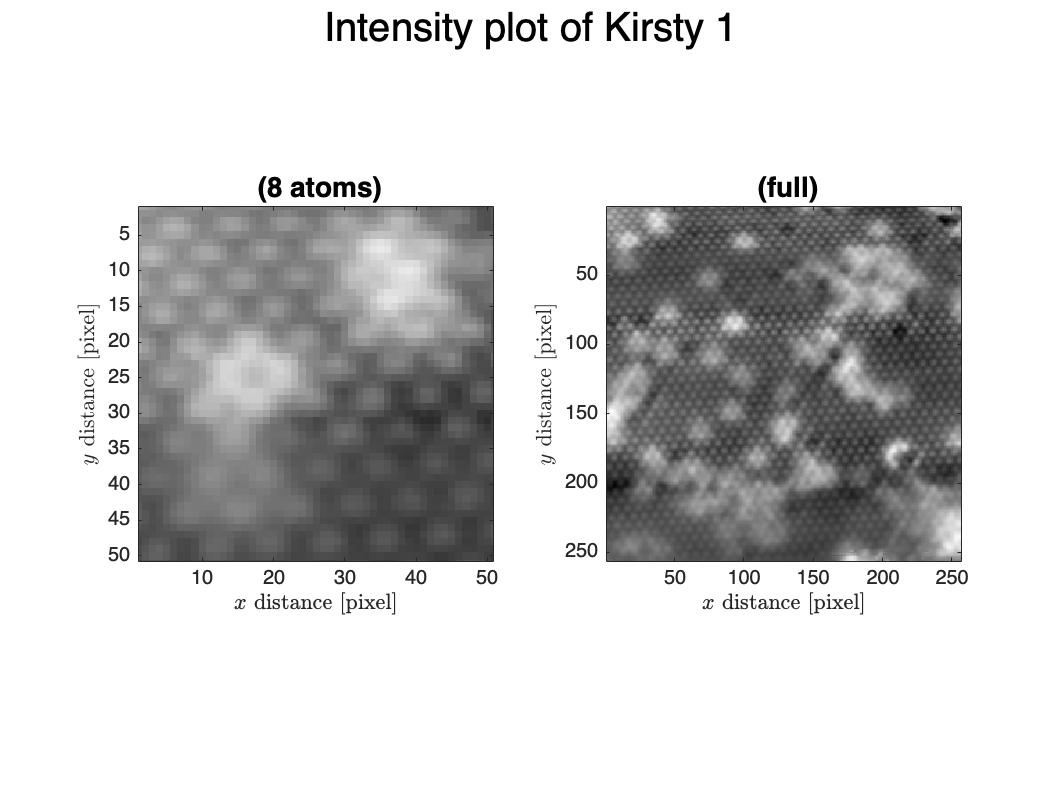


crystal_structures = ["square", "hexagonal"];
crystal = crystal_structures(size(Qbragg,2)-1);

atom_diameters = 1./sqrt((Qbragg(1,:)/image_length).^2+(Qbragg(2,:)/image_height).^2); % [pixel]
atom_diameter = mean(atom_diameters);

comboPlot(lattice,name,atom_diameter);


% distortion, noise, proportion weights in selecting lambda
lambda_scoring_weights = [1 1 0.05];

for ctr = 1:size(Qbragg,2)
    disp("Q_" + ctr + " = (" + Qbragg(1,ctr) + ", " + ...
        Qbragg(2,ctr) + ") [FFT units]")
end

Q_1 = (36.0526, 18.0829) [FFT units]
Q_2 = (2.366, 40.2639) [FFT units]
Q_3 = (-33.6865, 22.181) [FFT units]



disp("lattice constant = " + atom_diameter + " [pixel]");

lattice constant = 6.3471 [pixel]


disp("crystal structure: " + crystal);

crystal structure: hexagonal



confidence_level = 0.9999999;

Pre-processing the inputs, converting units. You might probably would't want to edit these.

lambda = 0.2;

disp("Lambda used = " + lambda);

Lambda used = 0.2



lambda = lambda*2*pi/atom_diameter;

Qbragg = Qbragg * 2*pi ./ (vecnorm(Qbragg)*atom_diameter);

zscore = zscorer(confidence_level);

## 2    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

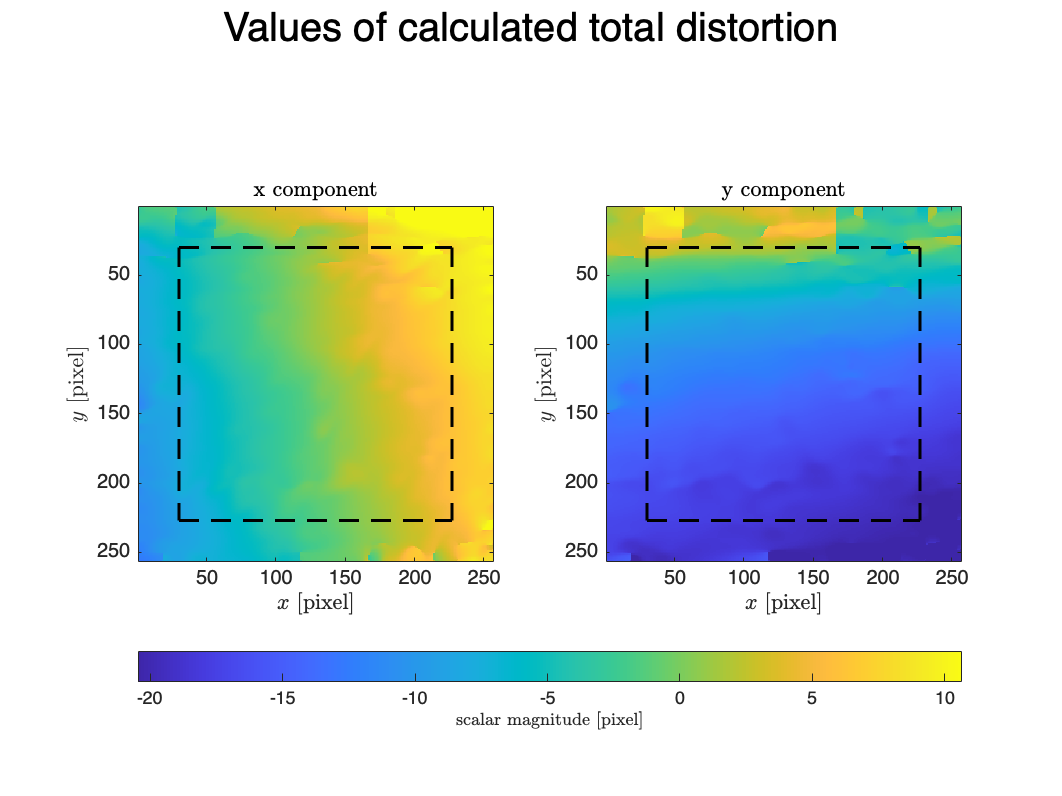

ucalc = myConv(lattice,Qbragg,lambda,zscore);

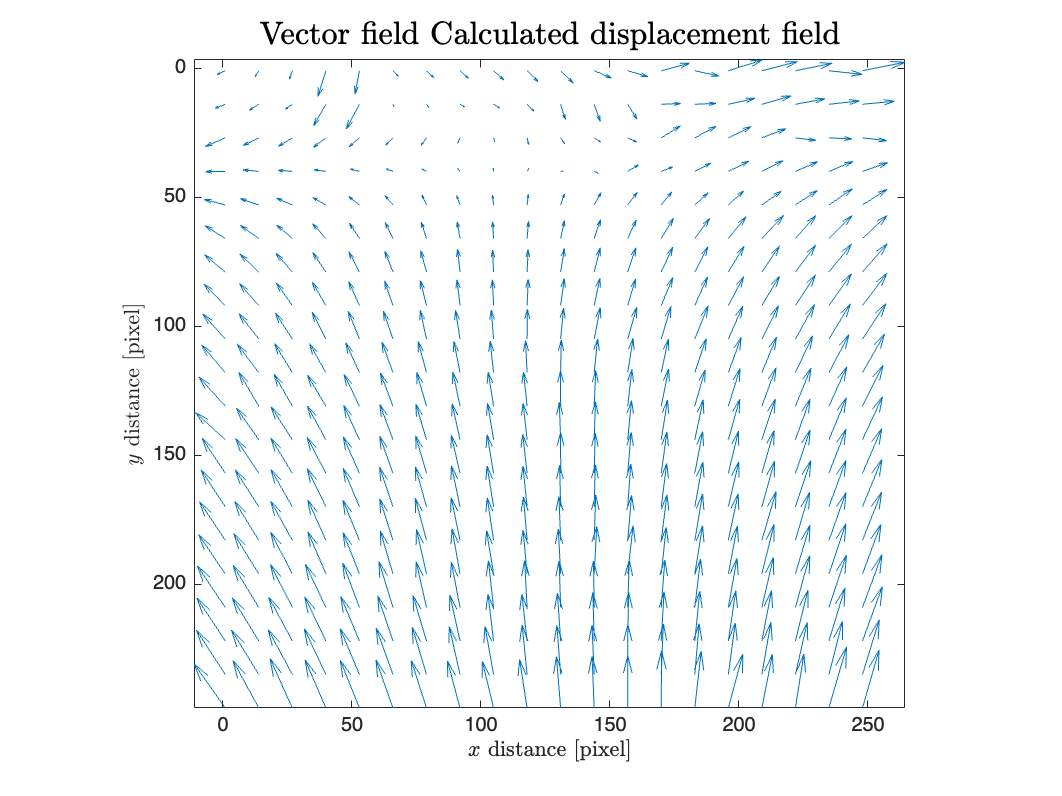


uPlot(ucalc,"Calculated displacement field");


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 39204 (59.8206%)


## 3    Calculating physical strain

From the equation given above, the physical strain can be obtained by subtracting the smooth, third-digree polynomial imaging distortion from the total distortion.

[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore);

Doing polynomial fit using MATLAB's poly33.


% fitPlot(fitresultx, ucalc(:,:,1), "$u_x$", lambda,zscore);
[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore);

Doing polynomial fit using MATLAB's poly33.


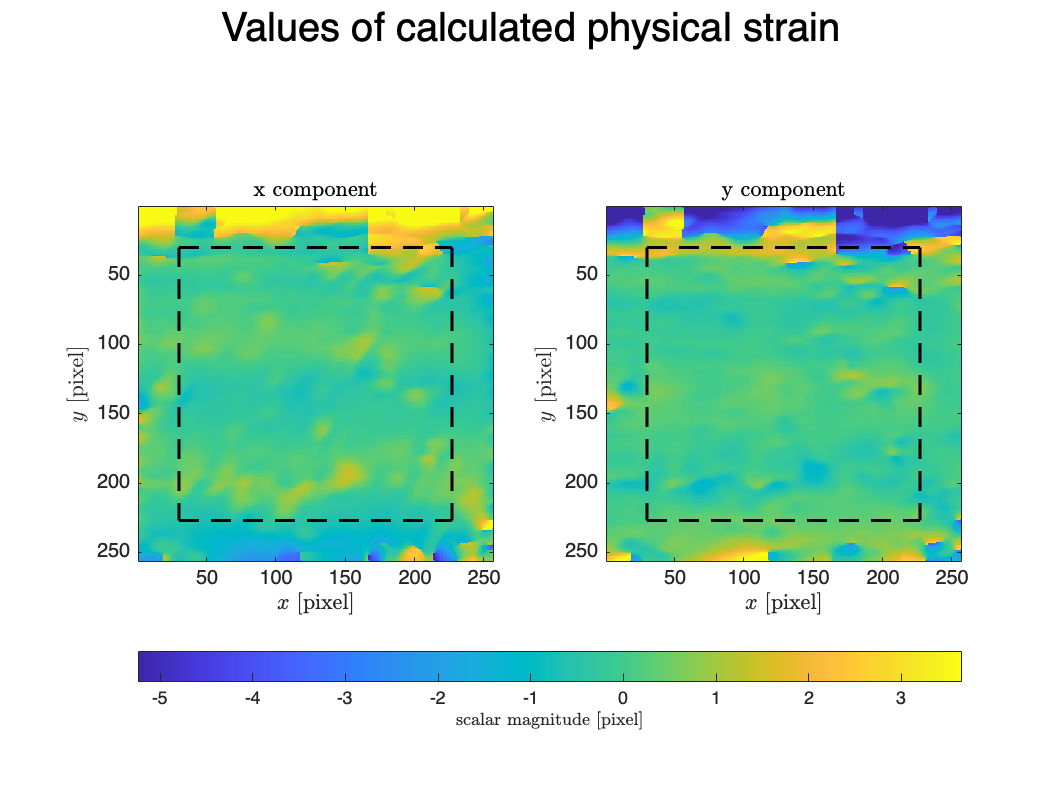

% fitPlot(fitresulty, ucalc(:,:,2), "$u_y$", lambda,zscore);

resx = outputx.residuals/atom_diameter;
resy = outputy.residuals/atom_diameter;
mu = zeros(2,1); sigma = zeros(2,1);
mu(1) = mean(resx); % [lattice constant]
sigma(1) = std(resx,1); % [lattice constant]
mu(2) = mean(resy); % [lattice constant]
sigma(2) = std(resy,1); % [lattice constant]

% to adjust for the [0,1] range of coordinates x,y,t
% and to avoid 'bad equation condition' warning
[xi,yi] = meshgrid(0:1/image_length:(image_length-1)/image_length ...
    ,0:1/image_height:(image_height-1)/image_height);

strain = zeros(size(ucalc));
strain(:,:,1) = ucalc(:,:,1)-fitresultx(xi,yi);
strain(:,:,2) = ucalc(:,:,2)-fitresulty(xi,yi);

convPlot(strain(:,:,1),"calculated physical strain",strain(:,:,2),lambda,zscore);


disp("Physical strain along x = " + (sigma(1)) + " [lattice constant]");

Physical strain along x = 0.06394 [lattice constant]


disp("Physical strain along y = " + (sigma(2)) + " [lattice constant]");

Physical strain along y = 0.081768 [lattice constant]


The strain and it's first order partial derivatives are calculated and plotted. Biaxial and approximate uniaxial strain maps are also generated from the previous calculations.

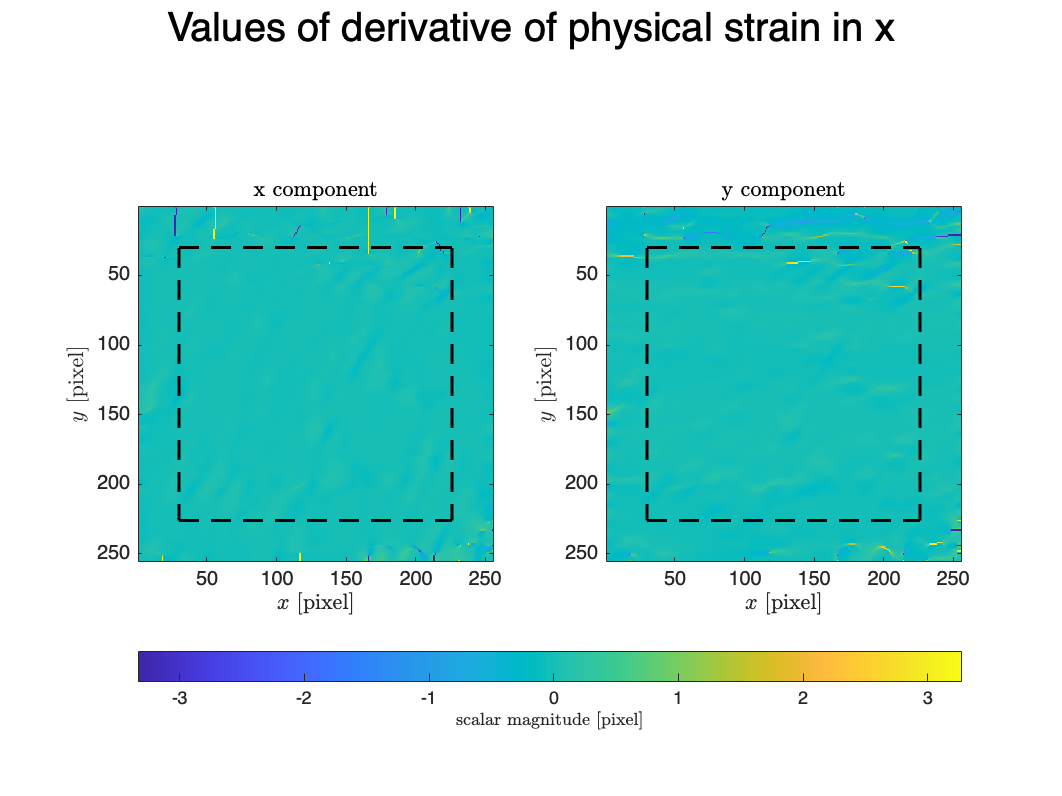

Sxdx = diff(strain(1:end-1,:,1),1,2);
Sxdy = diff(strain(:,1:end-1,1));
Sydx = diff(strain(1:end-1,:,2),1,2);
Sydy = diff(strain(:,1:end-1,2));
convPlot(Sxdx,"derivative of physical strain in x",Sxdy,lambda,zscore);

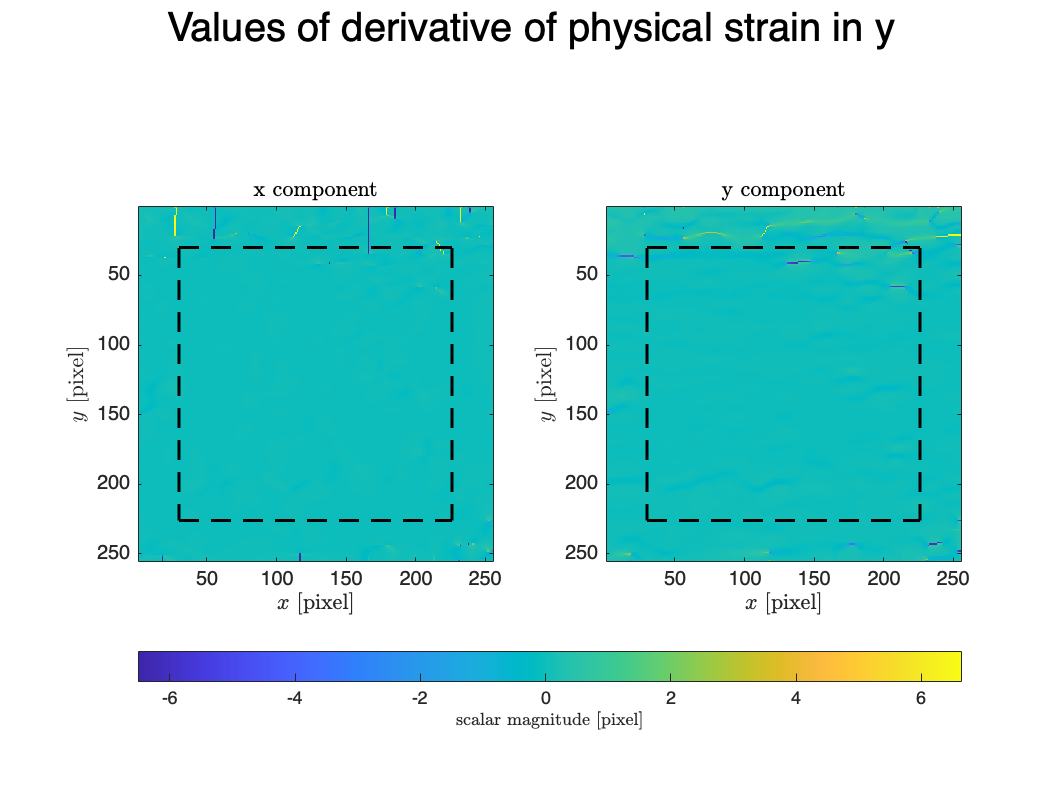

convPlot(Sydx,"derivative of physical strain in y",Sydy,lambda,zscore);

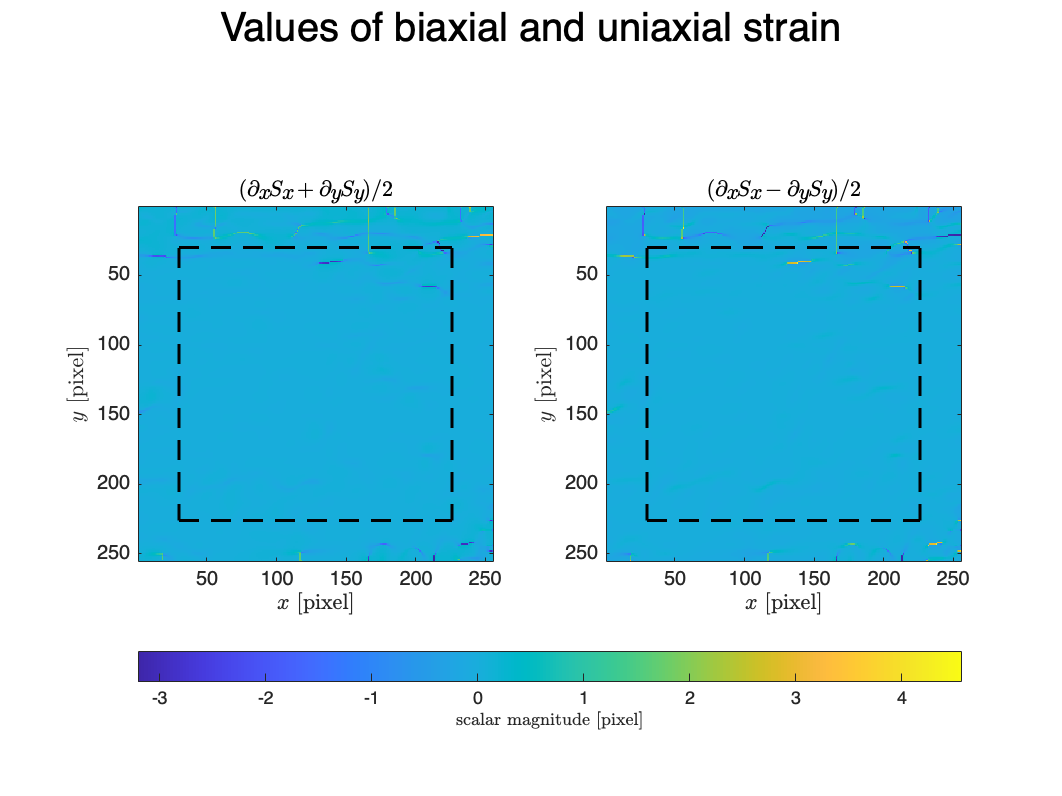

convPlot((Sxdx+Sydy)/2,"biaxial and uniaxial strain",(Sxdx-Sydy)/2,lambda,zscore);

## 4    Undistorting the image

Lastly, we undistort the image using my own undistort() function that in turn uses the imwarpConverse() function that I also built.

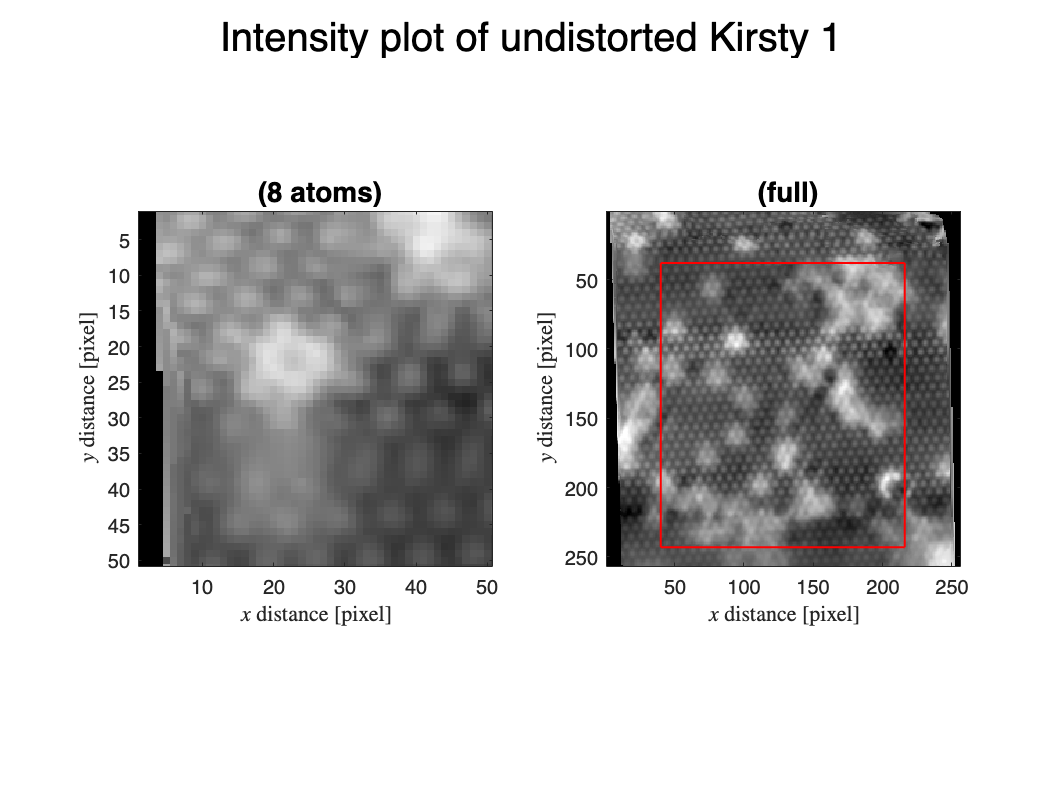

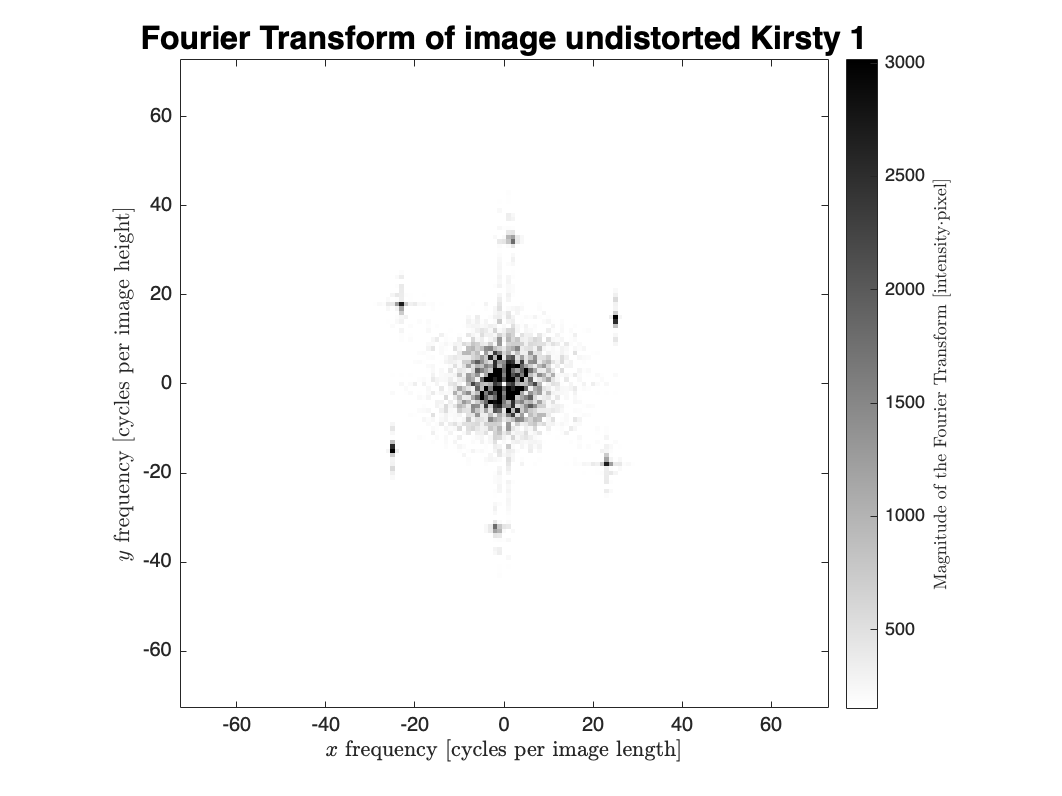

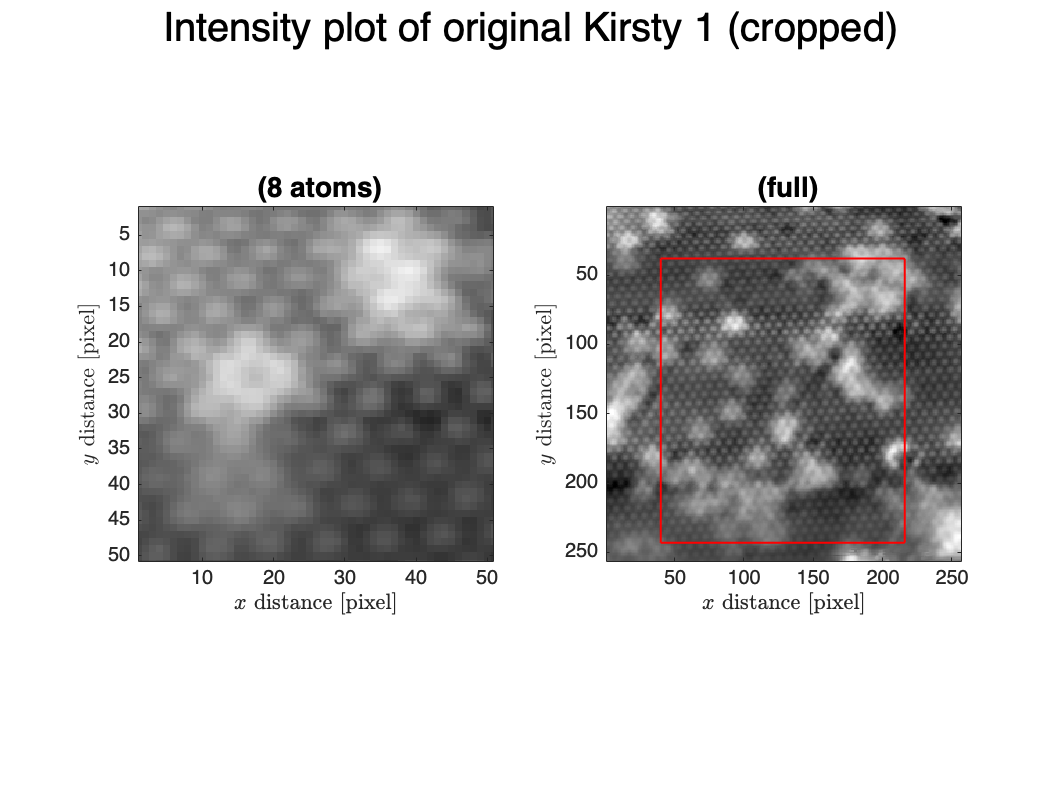

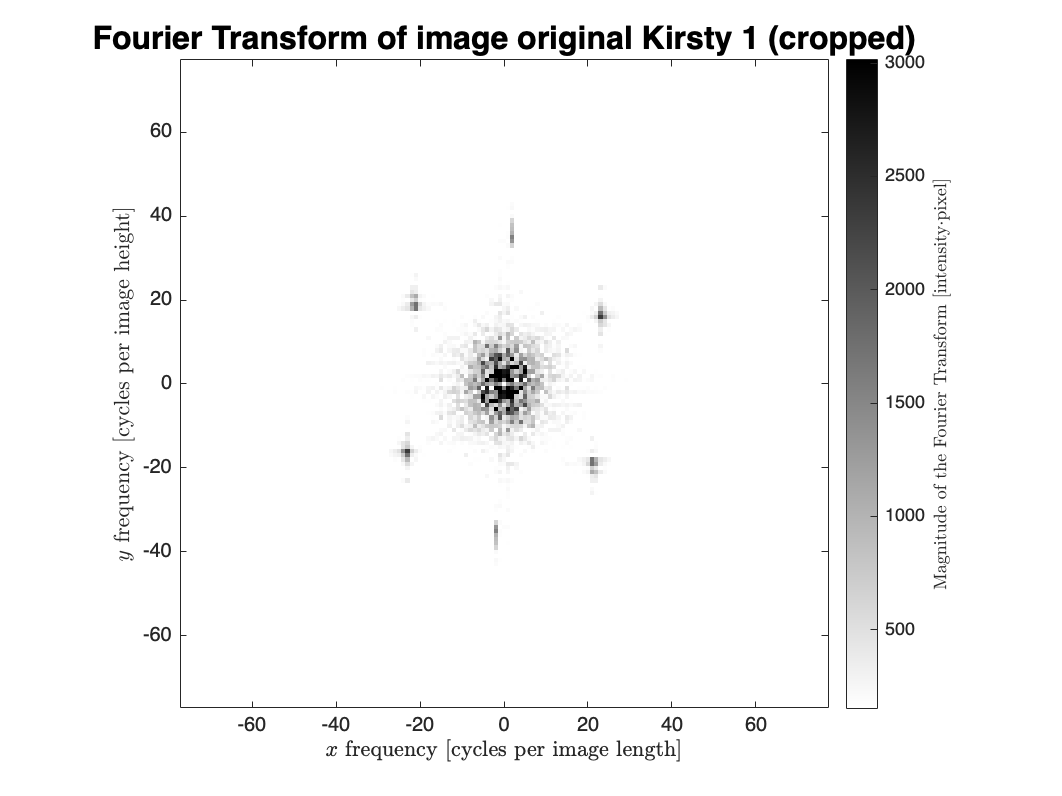

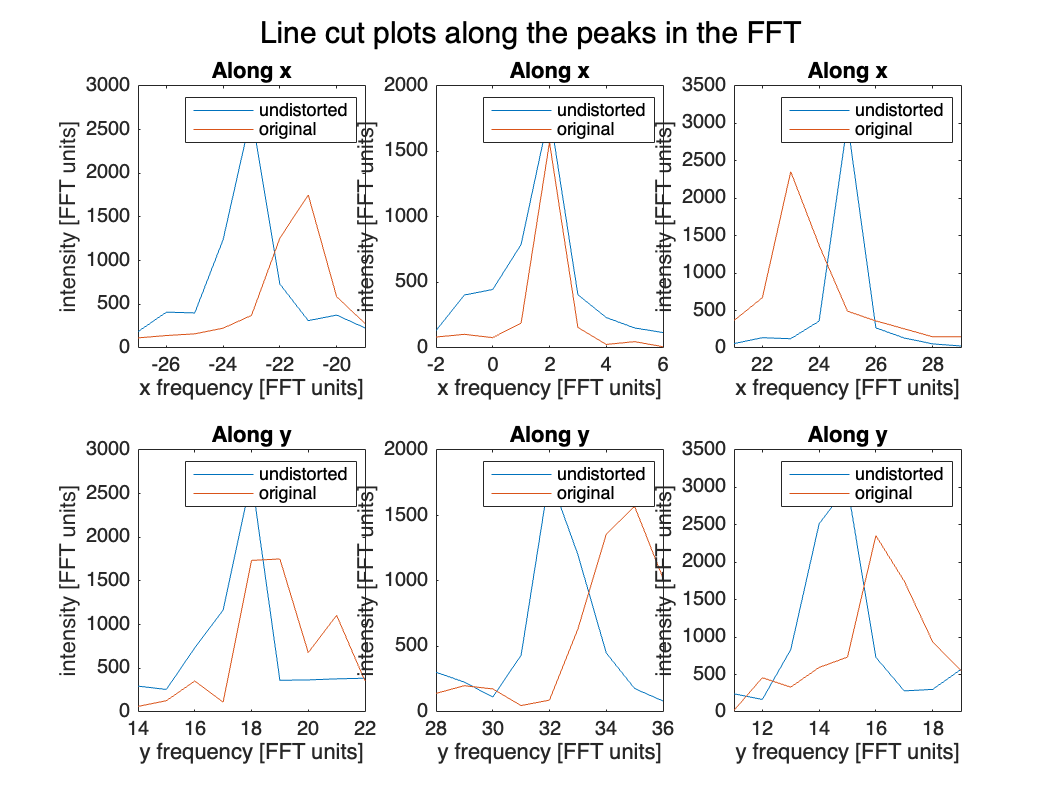

ulattice = undistort(lattice,-ucalc,atom_diameter,lambda,zscore, cscale='linear', ...
    name_undistorted="undistorted " + name, name_cropped="original " + name + " (cropped)", ...
    cryst_struct=crystal, linecuts=true);